clc; clear; close all;

u = @(x, y) x.^2 - y.^2;
K = @(X1, X2, Y1, Y2, Y_prime_1, Y_prime_2) -1/(2*pi) * ((X1 - Y1).*Y_prime_2 - (X2-Y2).*Y_prime_1)./((X1-Y1).^2+(X2-Y2).^2);

l1_theta = @(theta) cos(theta);
l2_theta = @(theta) sin(theta);
l_theta = @(theta) [l1_theta(theta), l2_theta(theta)];

r1_theta = @(theta) -sin(theta);
r2_theta = @(theta) cos(theta);
r_theta = @(theta) [r1_theta(theta), r2_theta(theta)];

r1_prime_theta = @(theta) -cos(theta);
r2_prime_theta = @(theta) -sin(theta);
r_prime_theta = @(theta) [r1_prime_theta(theta), r2_prime_theta(theta)];

nu_theta = @(theta) [r2_theta(theta), -r1_theta(theta)] ./ sqrt(r2_theta(theta).^2 + r1_theta(theta).^2);

n = 320;
theta_mesh = linspace(0, 2*pi-(2*pi/(n)), n)'

theta_mesh =          0
    0.0196
    0.0393
    0.0589
    0.0785
    0.0982
    0.1178
    0.1374
    0.1571
    0.1767


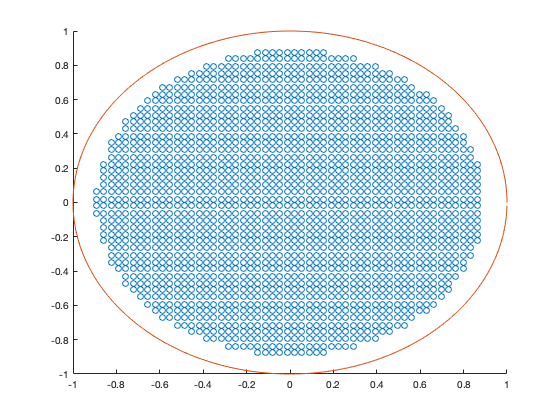

dtheta = 2*pi/n;

Y = l_theta(theta_mesh);
Y_prime = r_theta(theta_mesh);
Y_double_prime = r_prime_theta(theta_mesh);

[Y_j_1, Y_l_1] = meshgrid(Y(:, 1));
[Y_j_2, Y_l_2] = meshgrid(Y(:, 2));
[Y_prime_j_1, ~] = meshgrid(Y_prime(:, 1));
[Y_prime_j_2, ~] = meshgrid(Y_prime(:, 2));
msk_diagonals = logical(diag(ones(n, 1)));

A = -1/(2*pi)*((Y_l_1-Y_j_1).*Y_prime_j_2-(Y_l_2-Y_j_2).*Y_prime_j_1)./((Y_l_1-Y_j_1).^2+(Y_l_2-Y_j_2).^2).*sqrt(Y_prime_j_1.^2 + Y_prime_j_2.^2)*dtheta;
A(msk_diagonals) = -1/(4*pi)*(Y_prime(:, 2).*Y_double_prime(:, 1) - Y_prime(:, 1).*Y_double_prime(:, 2))./(Y_prime(:, 1).^2+Y_prime(:, 2).^2).*sqrt(Y_prime(:, 1).^2 + Y_prime(:, 2).^2)*dtheta + 1/2;
b = u(Y(:, 1), Y(:, 2));

phi_l = A\b;

x_mesh = linspace(-1.5, 1, 75);
y_mesh = linspace(-1, 1, 50);

[X_mesh, Y_mesh] = meshgrid(x_mesh, y_mesh);
in_interior = X_mesh.^2 + Y_mesh.^2 < 0.8;

figure;
scatter(X_mesh(in_interior), Y_mesh(in_interior))
hold on;
plot(Y(:, 1), Y(:, 2))

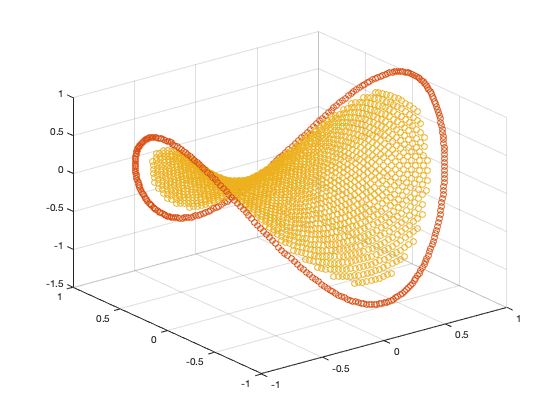


u_numeric = @(x, y) sum(K(x, y, Y(:, 1), Y(:, 2), Y_prime(:, 1), Y_prime(:, 2)).*phi_l.*sqrt(Y_prime(:, 1).^2 + Y_prime(:, 2).^2)*dtheta);
u_numeric_mesh = zeros(size(X_mesh));
for i = 1:size(X_mesh, 1)
    for j = 1:size(X_mesh, 2)
        if in_interior(i, j)
            u_numeric_mesh(i, j) = u_numeric(X_mesh(i, j), Y_mesh(i, j));
        end
    end
end


figure;
scatter3(X_mesh(in_interior), Y_mesh(in_interior), u_numeric_mesh(in_interior))
hold on;
scatter3(Y(:, 1), Y(:, 2), 1/2*phi_l + sum(repmat(phi_l', n, 1) * 1/(4*pi), 2))
scatter3(X_mesh(in_interior), Y_mesh(in_interior), u(X_mesh(in_interior), Y_mesh(in_interior)))

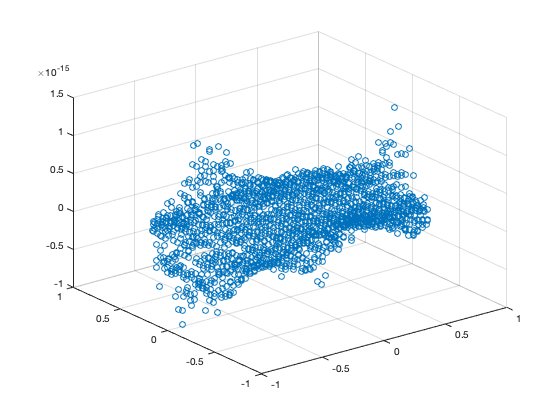


figure;
scatter3(X_mesh(in_interior), Y_mesh(in_interior), u(X_mesh(in_interior), Y_mesh(in_interior)) - u_numeric_mesh(in_interior))

max(abs(u(X_mesh(in_interior), Y_mesh(in_interior)) - u_numeric_mesh(in_interior)))

ans = 1.1102e-15

clc; clear; close all;

%%good implementation

u = @(x, y) x.^2 - y.^2;
K = @(X1, X2, Y1, Y2, Y_prime_1, Y_prime_2) -1/(2*pi) * ((X1 - Y1).*Y_prime_2 - (X2-Y2).*Y_prime_1)./(((X1-Y1).^2+(X2-Y2).^2).*sqrt(Y_prime_1.^2+Y_prime_2.^2));

l1_theta = @(theta) cos(theta)+0.65*cos(2*theta)-0.65;
l2_theta = @(theta) sin(theta);
l_theta = @(theta) [l1_theta(theta), l2_theta(theta)];

r1_theta = @(theta) -sin(theta)-1.3*sin(2*theta);
r2_theta = @(theta) cos(theta);
r_theta = @(theta) [r1_theta(theta), r2_theta(theta)];

r1_prime_theta = @(theta) -cos(theta)-2.6*cos(2*theta);
r2_prime_theta = @(theta) -sin(theta);
r_prime_theta = @(theta) [r1_prime_theta(theta), r2_prime_theta(theta)];

nu_theta = @(theta) [r2_theta(theta), -r1_theta(theta)] ./ sqrt(r2_theta(theta).^2 + r1_theta(theta).^2);

n = 160;
theta_mesh = linspace(0, 2*pi-(2*pi/(n)), n)'

theta_mesh =          0
    0.0393
    0.0785
    0.1178
    0.1571
    0.1963
    0.2356
    0.2749
    0.3142
    0.3534


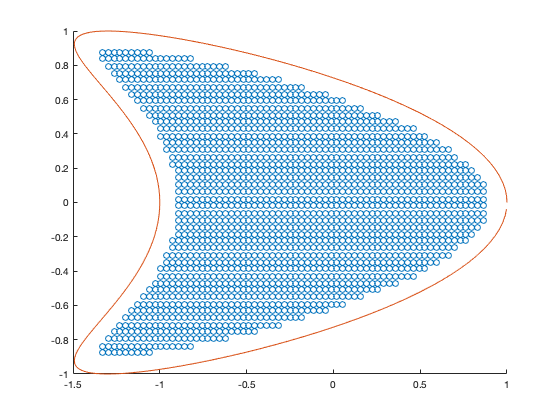

dtheta = 2*pi/n;

Y = l_theta(theta_mesh);
Y_prime = r_theta(theta_mesh);
Y_double_prime = r_prime_theta(theta_mesh);

[Y_j_1, Y_l_1] = meshgrid(Y(:, 1));
[Y_j_2, Y_l_2] = meshgrid(Y(:, 2));
[Y_prime_j_1, Y_prime_l_1] = meshgrid(Y_prime(:, 1));
[Y_prime_j_2, Y_prime_l_2] = meshgrid(Y_prime(:, 2));
msk_diagonals = logical(diag(ones(n, 1)));

A = K(Y_l_1, Y_l_2, Y_j_1, Y_j_2, Y_prime_j_1, Y_prime_j_2).*sqrt(Y_prime_j_1.^2 + Y_prime_j_2.^2)*dtheta;
A(msk_diagonals) = -1/(4*pi)*(Y_prime(:, 2).*Y_double_prime(:, 1) - Y_prime(:, 1).*Y_double_prime(:, 2))./(Y_prime(:, 1).^2+Y_prime(:, 2).^2)*dtheta+1/2;
b = u(Y(:, 1), Y(:, 2));

phi_l = A\b;

x_mesh = linspace(-1.5, 1, 75);
y_mesh = linspace(-1, 1, 50);

[X_mesh, Y_mesh] = meshgrid(x_mesh, y_mesh);
Y_interior = l_theta([theta_mesh; 2*pi]) - 0.1*nu_theta([theta_mesh; 2*pi]);
interior_msk = inpolygon_mesh(X_mesh, Y_mesh, Y_interior(:, 1), Y_interior(:, 2));

figure;
scatter(X_mesh(interior_msk), Y_mesh(interior_msk))
hold on;
plot(Y(:, 1), Y(:, 2))

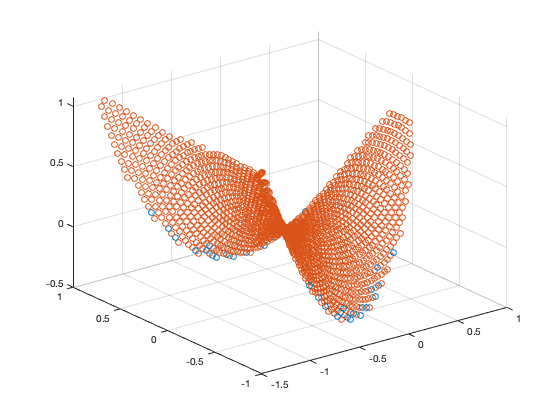


u_numeric = @(x, y) sum(K(x, y, Y(:, 1), Y(:, 2), Y_prime(:, 1), Y_prime(:, 2)).*phi_l.*sqrt(Y_prime(:, 1).^2 + Y_prime(:, 2).^2)*dtheta);
u_numeric_mesh = zeros(size(X_mesh));
for i = 1:size(X_mesh, 1)
    for j = 1:size(X_mesh, 2)
        if interior_msk(i, j)
            u_numeric_mesh(i, j) = u_numeric(X_mesh(i, j), Y_mesh(i, j));
        end
    end
end

figure;
scatter3(X_mesh(interior_msk), Y_mesh(interior_msk), u_numeric_mesh(interior_msk))
hold on;
scatter3(X_mesh(interior_msk), Y_mesh(interior_msk), u(X_mesh(interior_msk), Y_mesh(interior_msk)));


max(abs(u_numeric_mesh(interior_msk) - u(X_mesh(interior_msk), Y_mesh(interior_msk))))

ans = 7.8459e-04

clc; clear; close all;

u = @(x, y) x.^2 - y.^2;
K = @(X1, X2, Y1, Y2, Y_prime_1, Y_prime_2) -1/(2*pi) * ((X1 - Y1).*Y_prime_2 - (X2-Y2).*Y_prime_1)./(((X1-Y1).^2+(X2-Y2).^2).*sqrt(Y_prime_1.^2+Y_prime_2.^2));

% change of variable for graded mesh
p = 4;
v = @(s) (1/p-1/2).*((pi-s)/pi).^3+1/p*(s-pi)/pi+1/2;
w = @(s) 2*pi*(v(s)).^p./(v(s).^p+v(2*pi-s).^p);

v_prime = @(s) 1/(p*pi) - 3*(-1/2+1/p)*(pi-s).^2/pi^3;
w_prime = @(s) 2*pi * ((p*v(s).^(p-1).*v_prime(s))./(v(2*pi-s).^p+v(s).^p) - (v(s).^p.*(-p*v(2*pi-s).^(p-1).*v_prime(2*pi-s)+p*v(s).^(p-1).*v_prime(s)))./(v(2*pi-s).^p+v(s).^p).^2);

l1_theta = @(theta) 2*sin(theta/2)

l1_theta = function_handle with value:
    @(theta)2*sin(theta/2)


l2_theta = @(theta) -sin(theta);
l_theta = @(theta) [l1_theta(theta), l2_theta(theta)];

r1_theta = @(theta) cos(theta/2);
r2_theta = @(theta) -cos(theta);
r_theta = @(theta) [r1_theta(theta), r2_theta(theta)];

r1_prime_theta = @(theta) -0.5*sin(theta/2);
r2_prime_theta = @(theta) sin(theta);
r_prime_theta = @(theta) [r1_prime_theta(theta), r2_prime_theta(theta)];

nu_theta = @(theta) [r2_theta(theta), -r1_theta(theta)] ./ sqrt(r2_theta(theta).^2 + r1_theta(theta).^2);

n = 80;
theta_mesh = linspace(0, 2*pi-(2*pi/(n)), n)'

theta_mesh =          0
    0.0785
    0.1571
    0.2356
    0.3142
    0.3927
    0.4712
    0.5498
    0.6283
    0.7069


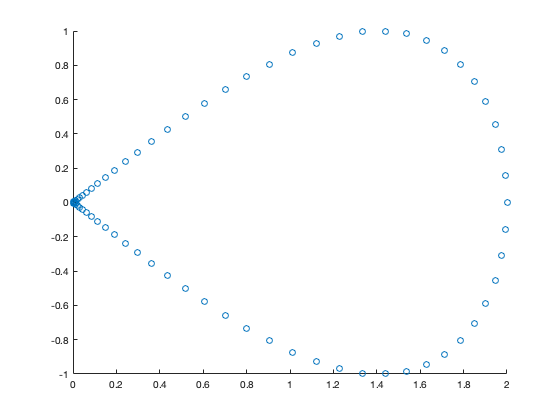

dtheta = 2*pi/n;

Y = l_theta(w(theta_mesh));
Y_prime = r_theta(w(theta_mesh));
Y_double_prime = r_prime_theta(w(theta_mesh));

[Y_j_1, Y_l_1] = meshgrid(Y(:, 1));
[Y_j_2, Y_l_2] = meshgrid(Y(:, 2));
[Y_prime_j_1, Y_prime_l_1] = meshgrid(Y_prime(:, 1));
[Y_prime_j_2, Y_prime_l_2] = meshgrid(Y_prime(:, 2));
msk_diagonals = logical(diag(ones(n, 1)));

w_prime_j = w_prime(theta_mesh);
W_prime_j = repmat(w_prime_j', n, 1);

figure;
scatter(Y(:, 1), Y(:, 2))

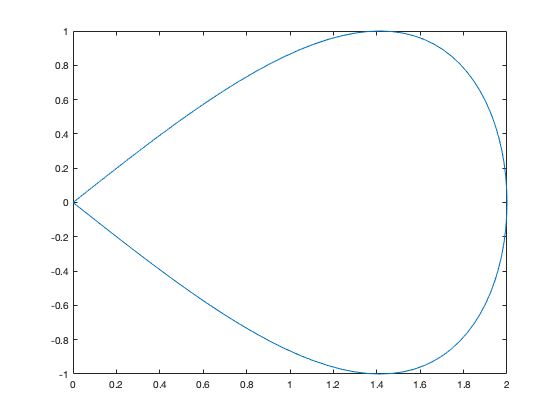


A = K(Y_l_1, Y_l_2, Y_j_1, Y_j_2, Y_prime_j_1, Y_prime_j_2).*sqrt(Y_prime_j_1.^2 + Y_prime_j_2.^2)*dtheta.*W_prime_j;
A(msk_diagonals) = -1/(4*pi)*(Y_prime(:, 2).*Y_double_prime(:, 1) - Y_prime(:, 1).*Y_double_prime(:, 2))./(Y_prime(:, 1).^2+Y_prime(:, 2).^2)*dtheta.*w_prime_j+1/2;
b = u(Y(:, 1), Y(:, 2));

phi_l = A\b;

x_mesh = linspace(0, 2, 75);
y_mesh = linspace(-1, 1, 50);

[X_mesh, Y_mesh] = meshgrid(x_mesh, y_mesh);
Y_interior = l_theta([theta_mesh; 2*pi]);
interior_msk = inpolygon_mesh(X_mesh, Y_mesh, Y_interior(:, 1), Y_interior(:, 2));

figure;
plot(Y_interior(:, 1), Y_interior(:, 2))

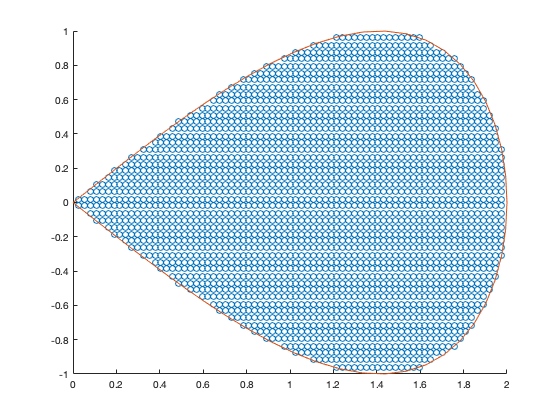


figure;
scatter(X_mesh(interior_msk), Y_mesh(interior_msk))
hold on;
plot(Y(:, 1), Y(:, 2))

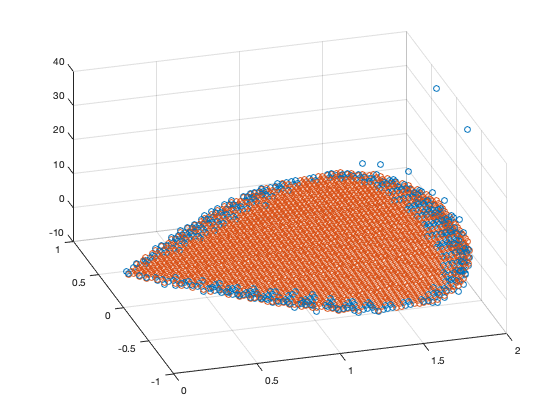


u_numeric = @(x, y) sum(K(x, y, Y(:, 1), Y(:, 2), Y_prime(:, 1), Y_prime(:, 2)).*phi_l.*sqrt(Y_prime(:, 1).^2 + Y_prime(:, 2).^2)*dtheta.*w_prime_j);
u_numeric_mesh = zeros(size(X_mesh));
for i = 1:size(X_mesh, 1)
    for j = 1:size(X_mesh, 2)
        if interior_msk(i, j)
            u_numeric_mesh(i, j) = u_numeric(X_mesh(i, j), Y_mesh(i, j));
        end
    end
end

figure;
scatter3(X_mesh(interior_msk), Y_mesh(interior_msk), u_numeric_mesh(interior_msk))
hold on;
scatter3(X_mesh(interior_msk), Y_mesh(interior_msk), u(X_mesh(interior_msk), Y_mesh(interior_msk)));


max(abs(u_numeric_mesh(interior_msk) - u(X_mesh(interior_msk), Y_mesh(interior_msk))))

ans = 32.9236